# Design of Machinery

# Mini Project : Cam Design

# Hana Shamsaei - 810600097

## Defining Parameters

clear,clc,close all 

syms L_2 L_3 L_5 L_6 theta

R_r = 0.5;
L = 5;

beta_2 = 2.4 - 1;
beta_3 = 3.1 - 2.4;
beta_5 = 5.2 - 4.1;
beta_6 = 2*pi - 5.2;

theta_2 = theta - 1;
theta_3 = theta - 2.4;
theta_5 = theta - 4.1;
theta_6 = theta - 5.2;

R0 = 10;

## Finding L_2, L_3, L_5, L_6

y2(theta) = L_2 * (theta_2/beta_2 - 1/sym(pi)*sin(sym(pi)*theta_2/beta_2));
y2_prime(theta) = diff(y2,theta);

y3(theta) = L_3 * sin((sym(pi)*theta_3/(2*beta_3)));
y3_prime(theta) = diff(y3,theta);

y5(theta) = L_5*cos(sym(pi)*theta_5/(2*beta_5));
y5_prime(theta) = diff(y5,theta);

y6(theta) = L_6*(1-theta_6/beta_6 - 1/sym(pi)*sin(sym(pi)*theta_6/beta_6));
y6_prime(theta) = diff(y6,theta);

eq(1) = y2_prime(2.4) == y3_prime(2.4);
eq(2) = y5_prime(5.2) == y6_prime(5.2);
eq(3) = L_2 + L_3 == L;
eq(4) = L_5 + L_6 == L;

[L2 L3 L5 L6] = vpasolve(eq , [L_2 L_3 L_5 L_6])

$$L2 = 3.0550773517582864469029769397698$$

$$L3 = 1.9449226482417135530970230602302$$

$$L5 = 2.8194548007560065355030212764034$$

$$L6 = 2.1805451992439934644969787235966$$

## Defining the time for each kind of motion

t1 = 0 : 0.01 :1;
t2 = 1 : 0.01 : 2.4;
t3 = 2.4 : 0.01 : 3.1;
t4 = 3.1 : 0.01 : 4.1;
t5 = 4.1 : 0.01 : 5.2;
t6 = 5.2 : 0.01 : 2*pi;

## Substituting the lengths found in the function of each motion

($\left.\textrm{For}\;\textrm{both}\;y^{\prime } \;\textrm{and}\;y^{\prime \prime } \right)$

y1 = zeros(size(t1));
y2 = subs(y2,L_2,L2);
y3 = subs(y3,L_3,L3)+L2;
y4 = L*ones(size(t4));
y5 = subs(y5,L_5,L5)+L6;
y6 = subs(y6,L_6,L6);

y1_prime = zeros(size(t4));
y2_prime = subs(y2_prime,L_2,L2);
y3_prime = subs(y3_prime,L_3,L3);
y4_prime = zeros(size(t4));
y5_prime = subs(y5_prime,L_5,L5);
y6_prime = subs(y6_prime,L_6,L6);

## Displacement diagram of the follower

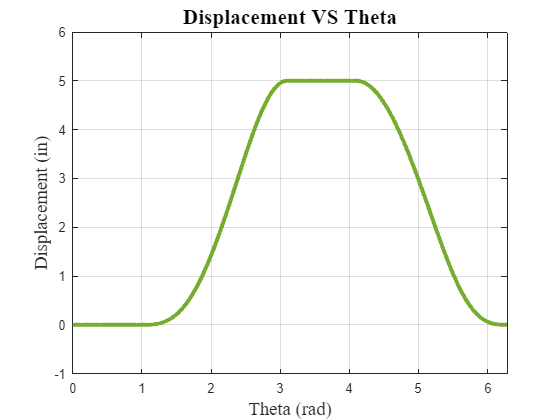

t = [t1 t2 t3 t4 t5 t6];
y = [y1 y2(t2) y3(t3) y4 y5(t5) y6(t6)];
plot(t,y,'LineWidth',3,'color',[0.4660 0.6740 0.1880])
xlim([0,2*pi])
ylim([-1,6])
grid on
title('Displacement VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Displacement (in)','FontName',"Times New Roman","FontSize",14)

## Velocity diagram of the follower

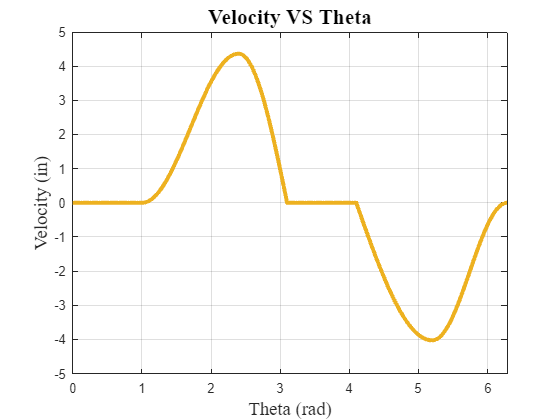

y_prime = [y1_prime, y2_prime(t2), y3_prime(t3), y4_prime, y5_prime(t5), y6_prime(t6)];
plot(t,y_prime,'LineWidth',3,'color',[0.9290 0.6940 0.1250])
xlim([0,2*pi])
grid on
title('Velocity VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Velocity (in)','FontName',"Times New Roman","FontSize",14)

## Acceleration diagram of the follower

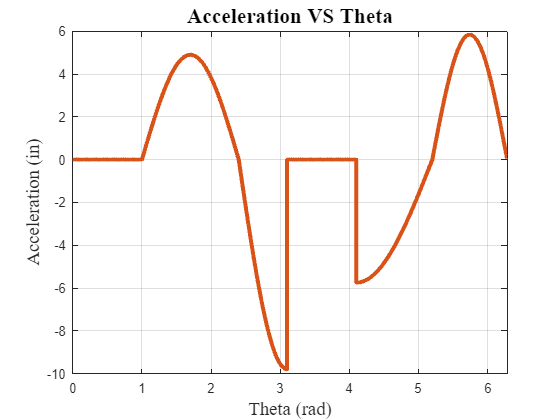

y1_dprime = zeros(size(t4));
y2_dprime = diff(y2,theta,2);
y3_dprime = diff(y3,theta,2);
y4_dprime = zeros(size(t4));
y5_dprime = diff(y5,theta,2);
y6_dprime = diff(y6,theta,2);

% -------------------------------------------------------------------------------------------

y_dprime = [y1_dprime, y2_dprime(t2), y3_dprime(t3), y4_dprime, y5_dprime(t5), y6_dprime(t6)];
plot(t,y_dprime,'LineWidth',3,'color',[0.8500 0.3250 0.0980])
xlim([0,2*pi])
grid on
title('Acceleration VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Acceleration (in)','FontName',"Times New Roman","FontSize",14)

## Defining parameters needed for plotting the pitch curve and cam curve and rho

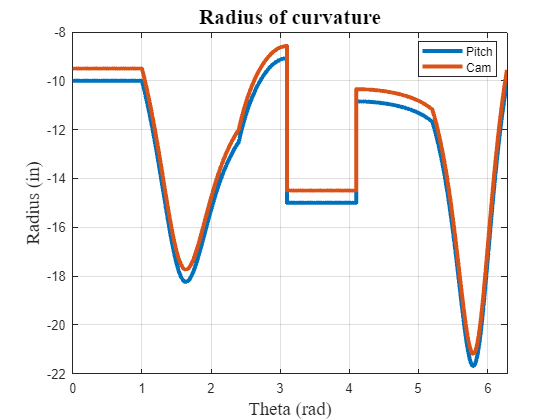

theta = t;

u = (R0 + y).*sin(theta);
v = (R0 + y).*cos(theta);

u_prime = y_prime.*sin(theta) + (R0 + y).*cos(theta);
v_prime = y_prime.*cos(theta) - (R0 + y).*sin(theta);

u_dprime = y_dprime.*sin(theta) + 2*y_prime.*cos(theta) - (R0+y).*sin(theta);
v_dprime = y_dprime.*cos(theta) - 2*y_prime.*sin(theta) - (R0+y).*cos(theta);

w_prime = sqrt(u_prime.^2 + v_prime.^2);

rho = w_prime.^3./(u_prime.*v_dprime - v_prime.*u_dprime);
rho_cam = rho + R_r;

% -------------------------------------------------------------------------------------------

plot(t,rho,'LineWidth',3,'color',[0 0.4470 0.7410])
grid on
title('Radius of curvature','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
hold on
xlim([0,2*pi])
plot(t,rho_cam,'LineWidth',3,'color',[0.8500 0.3250 0.0980])
legend({'Pitch','Cam'})
hold off

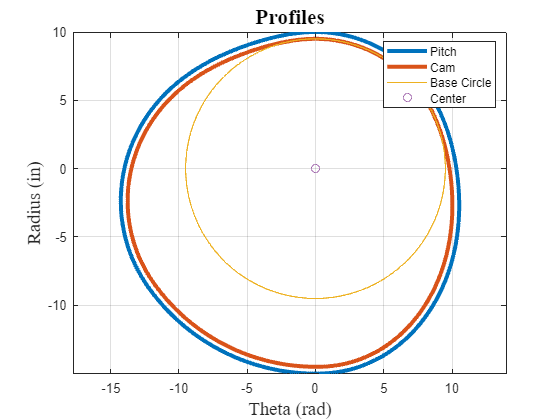

plot(u,v,'LineWidth',3,'color',[0 0.4470 0.7410])
grid on
title('Profiles','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
hold on
u_cam = u + R_r.*(v_prime./w_prime);
v_cam = v - R_r.*(u_prime./w_prime);
plot(u_cam,v_cam,'LineWidth',3,'color',[0.8500 0.3250 0.0980])
plot((R0-R_r)*cos(theta),(R0-R_r)*sin(theta))
plot(0,0,'o')
legend({'Pitch','Cam','Base Circle','Center'})
axis equal
hold off

## Pressure Angle

phi = acos((-v_prime./w_prime).*sin(theta) + (u_prime./w_prime).*cos(theta));
plot(t,phi*180/pi,'LineWidth',3,"Color",[0.494 0.184 0.556])

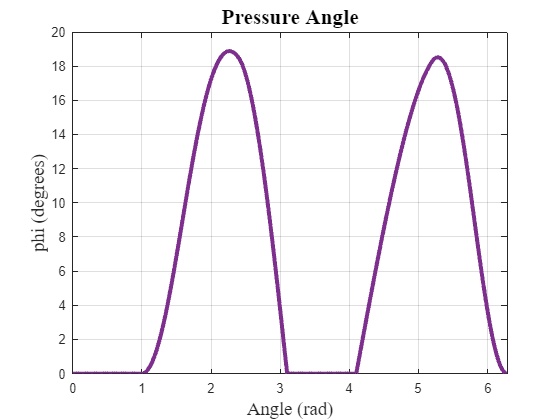

grid on
xlim([0,2*pi])
title('Pressure Angle','FontName',"Times New Roman","FontSize",16)
xlabel('Angle (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('phi (degrees)','FontName',"Times New Roman","FontSize",14)

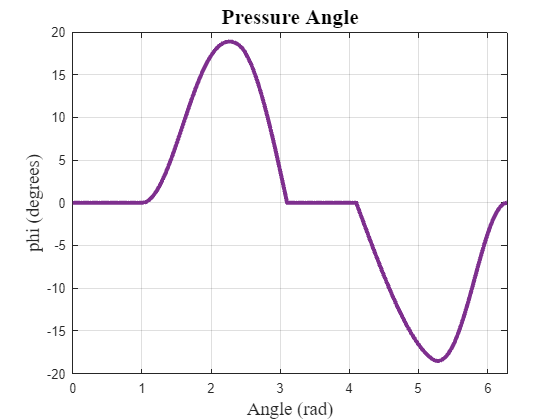

phi1 = atan(y_prime./(R0+y));
plot(t,phi1*180/pi,'LineWidth',3,"Color",[0.494 0.184 0.556])
grid on
xlim([0,2*pi])
title('Pressure Angle','FontName',"Times New Roman","FontSize",16)
xlabel('Angle (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('phi (degrees)','FontName',"Times New Roman","FontSize",14)

# Second Case (for Qs3)

## Defining Parameters

syms L_22 L_33 L_55 L_66 thetaa

R_r = 0.5;
L = 5;

thetaa_2 = thetaa - 1;
thetaa_3 = thetaa - 2.4;
thetaa_5 = thetaa - 4.1;
thetaa_6 = thetaa - 5.2;

R0 = 10;

## Finding L_2, L_3, L_5, L_6 

y22(thetaa) = L_22 * (1-cos((pi*thetaa_2/(2*beta_2))));
y22_prime(thetaa) = diff(y22,thetaa);

y33(thetaa) = L_33 * (thetaa_3/beta_3 + 1/sym(pi)*sin(sym(pi)*thetaa_3/beta_3));
y33_prime(thetaa) = diff(y33,thetaa);


y66(thetaa) = L_66*(1-sin(sym(pi)*thetaa_6/(2*beta_6)));
y66_prime(thetaa) = diff(y66,thetaa);

y55(thetaa) = L_55*(1-thetaa_5/beta_5 + 1/sym(pi)*sin(sym(pi)*thetaa_5/beta_5));
y55_prime(thetaa) = diff(y55,thetaa);

eq(1) = y22_prime(2.4) == y33_prime(2.4);
eq(2) = y55_prime(5.2) == y66_prime(5.2);
eq(3) = L_22 + L_33 == L;
eq(4) = L_55 + L_66 == L;

[L22 L33 L55 L66] = vpasolve(eq , [L_22 L_33 L_55 L_66])

$$L22 = 3.5901509993826690672770371660517$$

$$L33 = 1.4098490006173309327229628339483$$

$$L55 = 2.2184984010571236755241190853301$$

$$L66 = 2.7815015989428763244758809146699$$

## Substituting the lengths found in the function of each motion

($\left.\textrm{For}\;\textrm{both}\;y^{\prime } \;\textrm{and}\;y^{\prime \prime } \right)$

y1 = zeros(size(t1));
y22 = subs(y22,L_22,L22);
y33 = subs(y33,L_33,L33)+L22;
y4 = L*ones(size(t4));
y55 = subs(y55,L_55,L55)+L66;
y66 = subs(y66,L_66,L66);

y1_prime = zeros(size(t4));
y22_prime = subs(y22_prime,L_22,L22);
y33_prime = subs(y33_prime,L_33,L33);
y4_prime = zeros(size(t4));
y55_prime = subs(y55_prime,L_55,L55);
y66_prime = subs(y66_prime,L_66,L66);

## Displacement diagram of the follower

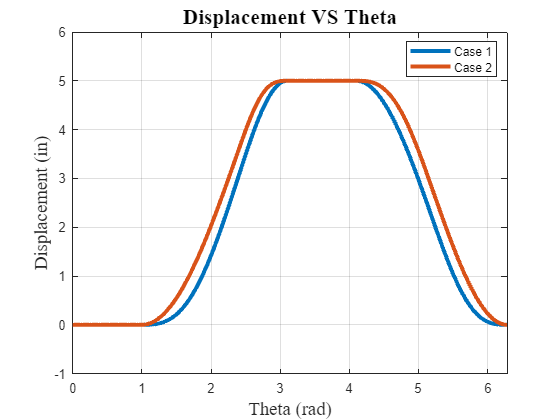

yy = [y1 y22(t2) y33(t3) y4 y55(t5) y66(t6)];
plot(t,y,'LineWidth',3)
hold on
plot(t,yy,'LineWidth',3)
xlim([0,2*pi])
ylim([-1,6])
grid on
title('Displacement VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Displacement (in)','FontName',"Times New Roman","FontSize",14)
legend({'Case 1','Case 2'})
hold off

## Velocity diagram of the follower

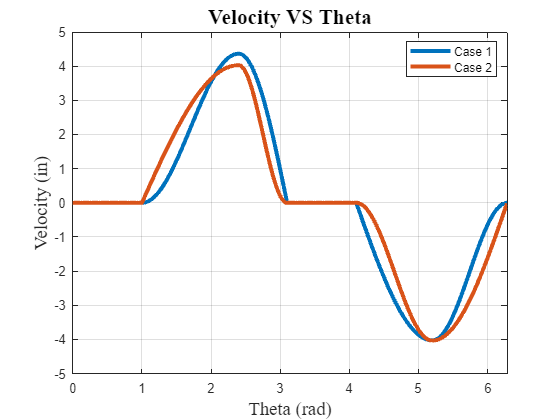

yy_prime = [y1_prime, y22_prime(t2), y33_prime(t3), y4_prime, y55_prime(t5), y66_prime(t6)];
plot(t,y_prime,'LineWidth',3)
hold on
plot(t,yy_prime,'LineWidth',3)
xlim([0,2*pi])
grid on
title('Velocity VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Velocity (in)','FontName',"Times New Roman","FontSize",14)
legend({'Case 1','Case 2'})
hold off

## Acceleration diagram of the follower

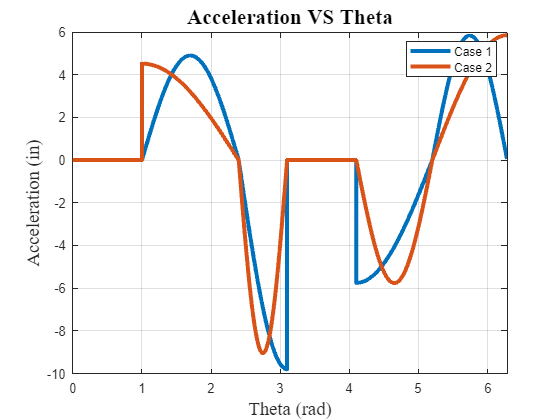

y1_dprime = zeros(size(t4));
y22_dprime = diff(y22,thetaa,2);
y33_dprime = diff(y33,thetaa,2);
y4_dprime = zeros(size(t4));
y55_dprime = diff(y55,thetaa,2);
y66_dprime = diff(y66,thetaa,2);

% -------------------------------------------------------------------------------------------

yy_dprime = [y1_dprime, y22_dprime(t2), y33_dprime(t3), y4_dprime, y55_dprime(t5), y66_dprime(t6)];
plot(t,y_dprime,'LineWidth',3)
hold on
plot(t,yy_dprime,'LineWidth',3)
xlim([0,2*pi])
grid on
title('Acceleration VS Theta','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Acceleration (in)','FontName',"Times New Roman","FontSize",14)
legend({'Case 1','Case 2'})
hold off

## Defining parameters needed for plotting the pitch curve and cam curve and rho

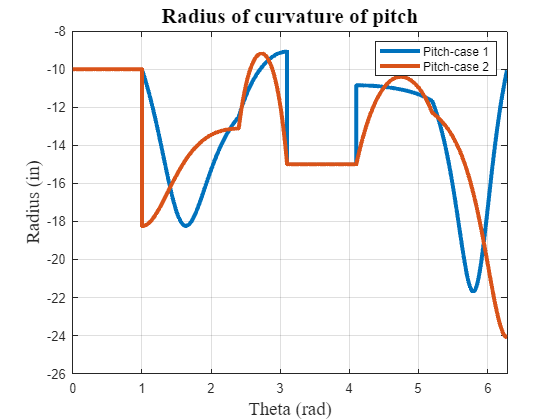

uu = (R0 + yy).*sin(theta);
vv = (R0 + yy).*cos(theta);

uu_prime = yy_prime.*sin(theta) + (R0 + yy).*cos(theta);
vv_prime = yy_prime.*cos(theta) - (R0 + yy).*sin(theta);

uu_dprime = yy_dprime.*sin(theta) + 2*yy_prime.*cos(theta) - (R0+yy).*sin(theta);
vv_dprime = yy_dprime.*cos(theta) - 2*yy_prime.*sin(theta) - (R0+yy).*cos(theta);

ww_prime = sqrt(uu_prime.^2 + vv_prime.^2);

rhoo = ww_prime.^3./(uu_prime.*vv_dprime - vv_prime.*uu_dprime);
rhoo_cam = rhoo + R_r;

% -------------------------------------------------------------------------------------------

%  Radius of curvature of pitch
%  Case 1
plot(t,rho,'LineWidth',3)
grid on
title('Radius of curvature of pitch','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
hold on
%  Case 2
plot(t,rhoo,'LineWidth',3)
xlim([0,2*pi])
legend({'Pitch-case 1','Pitch-case 2'})
hold off

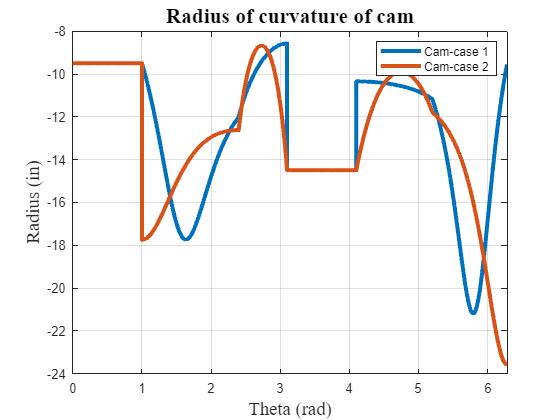

%  Radius of curvature of cam
%  Case 1
plot(t,rho_cam,'LineWidth',3)

grid on
title('Radius of curvature of cam','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
hold on
plot(t,rhoo_cam,'LineWidth',3)
xlim([0,2*pi])
legend({'Cam-case 1','Cam-case 2'})
hold off

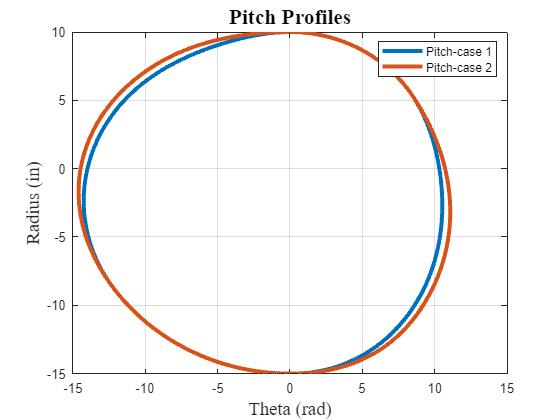

% -------------------------------------------------------------------------------------------

%  Pitch profile
%  Case 1
plot(u,v,'LineWidth',3)
grid on
title('Pitch Profiles','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
hold on
%  Case 2
plot(uu,vv,'LineWidth',3)
legend({'Pitch-case 1','Pitch-case 2'})
hold off

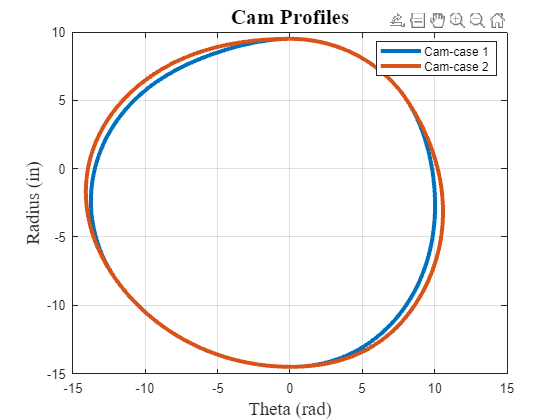


%  Cam profile
%  Case 1
plot(u_cam,v_cam,'LineWidth',3)
hold on
grid on
title('Cam Profiles','FontName',"Times New Roman","FontSize",16)
xlabel('Theta (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('Radius (in)','FontName',"Times New Roman","FontSize",14)
uu_cam = uu + R_r.*(vv_prime./ww_prime);
vv_cam = vv - R_r.*(uu_prime./ww_prime);
%  Case 2
plot(uu_cam,vv_cam,'LineWidth',3)
legend({'Cam-case 1','Cam-case 2'})
hold off

## Pressure Angle

phi = acos((-v_prime./w_prime).*sin(theta) + (u_prime./w_prime).*cos(theta));
phii = acos((-vv_prime./ww_prime).*sin(theta) + (uu_prime./ww_prime).*cos(theta));
plot(t,phi*180/pi,'LineWidth',3)

hold on
plot(t,phii*180/pi,'LineWidth',3)

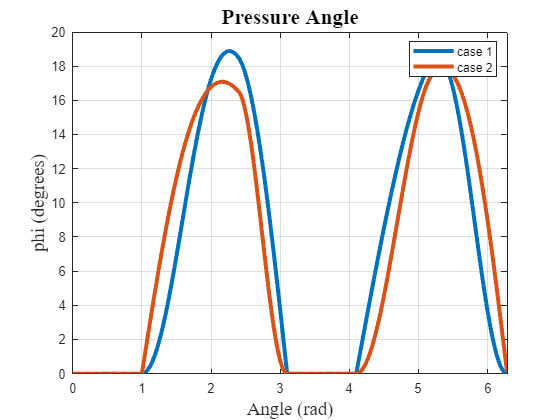

grid on
xlim([0,2*pi])
title('Pressure Angle','FontName',"Times New Roman","FontSize",16)
xlabel('Angle (rad)','FontName',"Times New Roman","FontSize",14)
ylabel('phi (degrees)','FontName',"Times New Roman","FontSize",14)
legend({'case 1','case 2'})
hold off